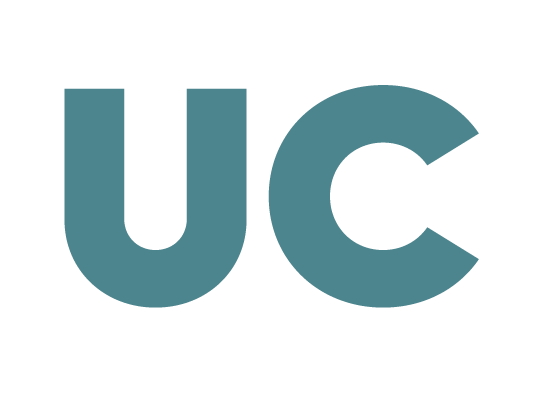

***Grado de Tecnologías de Telecomunicación***

**G282: Álgebra y Geometria**

# **Práctica 5: Espacios vectoriales (II)**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

format rat
clear all;

## **Coordenadas y cambio de base**

### Coordenadas

Como sabemos, podemos expresar cualquier vector de un subpacio vectorial $S$ como combinación lineal de los vectores de un sistema generador de $S$. Si además el sistema generador es base, esta combinación lineal es única, y sus coeficientes reciben el nombre de coordenadas. 

**Ejemplo 1**. Queremos hallar las coordenadas del vector (7,8,9) en la base B={(1 1 0), (1 2 0),(1 1 4)}.

Para empezar definimos la matriz B que tiene como columnas los vectores de la base B.

%matriz cuyas columnas son los vectores de la base
B=[ 1 1 0; 1 2 0 ; 1 1 4]'

B =        1              1              1       
       1              2              1       
       0              0              4       


Para hallar las coordenadas del vector (7,8,9) en la base B necesitamos resolver el siguiente sistema:


$$\left(\begin{array}{c}
     7\\  
     8\\  
     9\end{array}\right)_{BC}=
\alpha_1 \left(\begin{array}{c}
     1\\  
     1\\  
     0\end{array}\right)+\alpha_2 \left(\begin{array}{c}
     1\\  
     2\\  
     0\end{array}\right)+\alpha_3 \left(\begin{array}{c}
     1\\  
     1\\  
     4\end{array}\right)=\left(\begin{array}{ccc}
     1 & 1 & 1\\  
     1 & 2 & 1\\  
     0 & 0 & 4\end{array}\right)\left(\begin{array}{c}
     \alpha_1\\  
     \alpha_2\\  
     \alpha_3\end{array}\right)_{B}

\quad \rightarrow 
\left(\begin{array}{ccc}
     1 & 1 & 1\\  
     1 & 2 & 1\\  
     0 & 0 & 4\end{array}\right)\left(\begin{array}{c}
     \alpha_1\\  
     \alpha_2\\  
     \alpha_3\end{array}\right)_{B}=\left(\begin{array}{c}
     7\\  
     8\\  
     9\end{array}\right)_{BC}
$$


rank(B)     %rango 3. S.C.D

ans =        3       


v=[7 8 9]'; %coordenadas vector en la base canonica
vB=B\v      %coordenadas del vector en la base B

vB =       15/4     
       1       
       9/4     


Es decir, $(7,8,9)=\frac{15}{4}(1, 1 ,0)+(1, 2, 0)+\frac{9}{4}(1 ,1, 4)$. Las coordenadas del vector $(7,8,9)_{BC}$  en la base B son $(\frac{15}{4},1,\frac{9}{4})_{B}$

Resumiendo, tenemos que:


$$ \left(\begin{array}{c}
     7\\  
     8\\  
     9\end{array}\right)_{BC}= \left(\begin{array}{c}
     19/4\\  
     1\\  
     9/4\end{array}\right)_{B}  \quad \Leftrightarrow

7 \left(\begin{array}{c}
     1\\  
     0\\  
     0\end{array}\right)+8\left(\begin{array}{c}
     0\\  
     1\\  
     0\end{array}\right)+9
 \left(\begin{array}{c}
     0\\  
     0\\  
     1\end{array}\right)=
15/4 \left(\begin{array}{c}
     1\\  
     1\\  
     0\end{array}\right)+ 1 \left(\begin{array}{c}
     1\\  
     2\\  
     0\end{array}\right)+ 9/4 \left(\begin{array}{c}
     1\\  
     1\\  
     4\end{array}\right)$$


**Ejemplo 1 (continuación)**. Siguiendo con la base B={(1 1 0), (1 2 0),(1 1 4)}, queremos hallar las coordenadas del vector$(1,2,3)_B$ en la base canónica  BC={(1 0 0), (0 1 0),(0 0 1)}.

Es decir tenemos el vector $(1,2,3)_B$. Donde 1, 2 y 3 son las coordenadas del vector en la base B:


$$\left(\begin{array}{c}
     1\\  
    2\\  
     3\end{array}\right)_{B}=
1 \left(\begin{array}{c}
     1\\  
     1\\  
     0\end{array}\right)+2 \left(\begin{array}{c}
     1\\  
     2\\  
     0\end{array}\right)+3
 \left(\begin{array}{c}
     1\\  
     1\\  
     4\end{array}\right)$$


Ahora estamos buscando las coordenadas de ese mismo vector en la base canónica $(\alpha_1,\alpha_2,\alpha_3)_{BC}$


$$1 \left(\begin{array}{c}
     1\\  
     1\\  
     0\end{array}\right)+2 \left(\begin{array}{c}
     1\\  
     2\\  
     0\end{array}\right)+3
 \left(\begin{array}{c}
     1\\  
     1\\  
     4\end{array}\right)=\alpha_1 \left(\begin{array}{c}
     1\\  
     0\\  
     0\end{array}\right)+\alpha_2 \left(\begin{array}{c}
     0\\  
     1\\  
     0\end{array}\right)+\alpha_3
 \left(\begin{array}{c}
     0\\  
     0\\  
     1\end{array}\right)
= \left(\begin{array}{c}
     \alpha_1\\  
     \alpha_2\\  
     \alpha_3\end{array}\right)_{BC}
$$


simplemente necesitamos operar para hallarlas

wB=[1 2 3]';    %coordenadas del vector en la base B
wBC=wB(1)*B(:,1)+wB(2)*B(:,2)+wB(3)*B(:,3) %coordenadas del vector en la base BC

wBC =        6       
       8       
      12       


Ya tenemos la solución:$(\alpha_1,\alpha_2,\alpha_3)_{BC}=(6,8,12)
$. 

Resumiendo, podemos comprobar que:


$$ \left(\begin{array}{c}
     1\\  
     2\\  
     3\end{array}\right)_{B}= \left(\begin{array}{c}
     6\\  
     8\\  
     12\end{array}\right)_{BC}  \quad \Leftrightarrow  \quad
1 \left(\begin{array}{c}
     1\\  
     1\\  
     0\end{array}\right)+2 \left(\begin{array}{c}
     1\\  
     2\\  
     0\end{array}\right)+3
 \left(\begin{array}{c}
     1\\  
     1\\  
     4\end{array}\right)=6 \left(\begin{array}{c}
     1\\  
     0\\  
     0\end{array}\right)+8\left(\begin{array}{c}
     0\\  
     1\\  
     0\end{array}\right)+12
 \left(\begin{array}{c}
     0\\  
     0\\  
     1\end{array}\right)

$$


### Matriz cambio de base

Un subespacio o espacio vectorial tiene infinitas bases posibles, todas con el mismo número de vectores (dimensión del subespacio o dimensión del espacio). Un vector tendrá unas coordenadas diferentes dependiendo de la base. La matriz de cambio de base $M_{B_1 \rightarrow B_2}$nos permite obtener las coordenadar del vector en la base $B_2
$ a partir de las coordenadas del vector en la base $B_1
$. 

**Ejemplo 2**. Los subespacios $S_1
$ y $S_2
$ tienen las siguientes bases

%vectores base B1
v1=[1 0]'; v2=[1 3]';
%vectores base B2
u1=[0 1]'; u2=[1 1]';

Para obtener las matrices de cambio de base $M_{B_1 \rightarrow B_2}$ y $M_{B_2 \rightarrow B_1}$, la forma más sencilla es pasar primero de coordenadas de B1 y B2 a coodenadas en base canónica. Aunque hay más formas de obtener las matrices de cambio de base, por simplicidad, en este curso solo vamos a ver esta. Veamos un ejemplo.

Pongamos que tenemos un vector en base canónica con coordenadas${\;\left(\gamma_1 \;,\;\gamma_2 \right)}_{\textrm{BC}} \ldotp \;$Las coordenadas de dicho vector en la base B1 serán${\left(\alpha_1 ,\alpha_2 \right)}_{\textrm{B1}}$y podrían calcularse resolviendo el siguiente sistema:

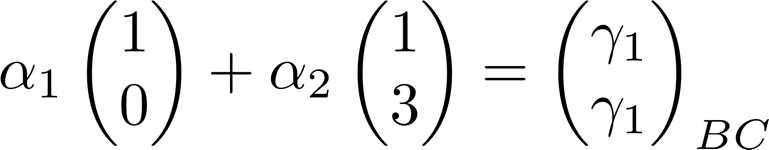

De la misma forma, podríamos calcular las coordenadas del mismo vector ${\;\left(\gamma_1 \;,\;\gamma_2 \right)}_{\textrm{BC}}$ en la base B2, que serían ${\left(\beta_1 ,\beta_2 \right)}_{\textrm{B2}}$:

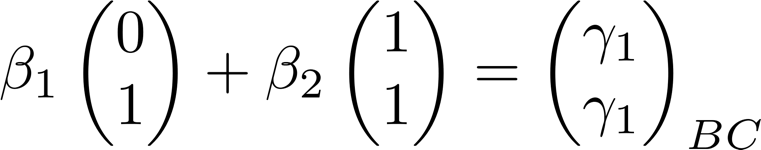

 Si igualamos ambas expresiones, obtendremos la relación entre las coordenadas de la base B1 y B2. 

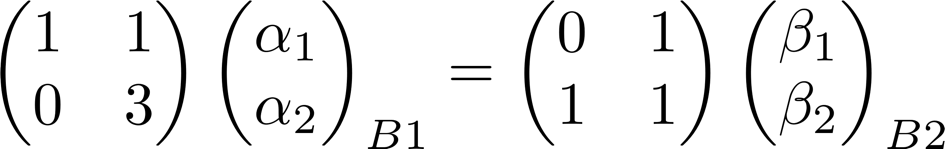

Para obtener las coordenadas de un vector en la base B2 conociendo sus coordenadas en la base B1 tendremos que despejar de la ecuación anterior ${\left(\beta_1 ,\beta_2 \right)}_{\textrm{B2}}$. Es decir, tendríamos que multiplicar las coordenadas del vector en la base B1 por la siguiente matriz:

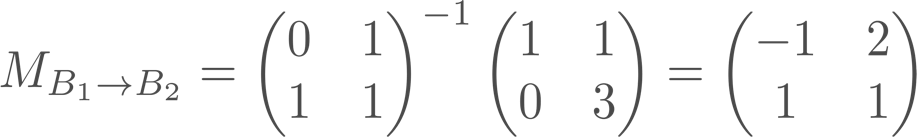

De la misma forma, para pasar de coordenadas de B2 a B1 haríamos lo siguiente:

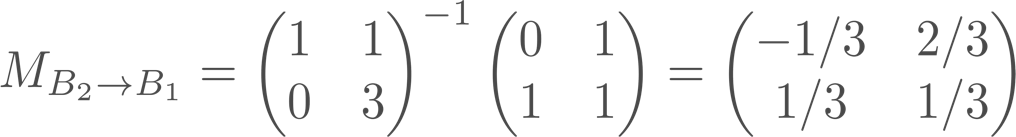

Fíjate, $M_{B_1 \rightarrow B_2}$ y $M_{B_2 \rightarrow B_1}$son una la inversa de la otra.

$M_{B_1 \rightarrow B_2}$ y $M_{B_2 \rightarrow B_1}$ son las coordenadas de cambio de base entre B1 y B2 y entre B2 y B1, respectivamente.

B1=[v1 v2];
B2=[u1 u2];
% matriz de cambio de base de B1->B2
MB1B2=inv(B2)*B1

MB1B2 =       -1              2       
       1              1       


Esta matriz  $M_{B_1 \rightarrow B_2}$ nos permite obtener muy fácilmente las coordenadas en la base $B_2
$ de cualquier vector expresado en la base $B_1
$. 

Por ejemplo, dado $(2,1)_{B_1}$ obtenemos que sus coordenadas en la base $B_2
$ son $(0,3)_{B_2}$

wB1=[2,1]'; %coordenadas del vector en la base B1
wB2=MB1B2*wB1 %coordenadas del vector en la base B2

wB2 =        0       
       3       


Para obtener la matriz de cambio de base  $M_{B_2 \rightarrow B_1}$ , podemos seguir un procedimiento análogo al anterior. O simplemente utilizar que $M_{B_2 \rightarrow B_1}$ es la inversa de $M_{B_1 \rightarrow B_2}$.

MB2B1=inv(MB1B2)

MB2B1 =       -1/3            2/3     
       1/3            1/3     


Por ejemplo, siguiendo con el ejemplo anterior podemos comprobar  que $(0,3)_{B_2}$ corresponde con $(2,1)_{B_1}$:

MB2B1*wB2 %coincide con wB1

ans =        2       
       1       


**Ejercicio.** Prueba a resolver el ejemplo 1 del apartado anterior utilizando las matrices cambio de base. En dicho ejercicio las bases son B={(1 1 0), (1 2 0),(1 1 4)} y la base canónica. 